## Linear Parametrization

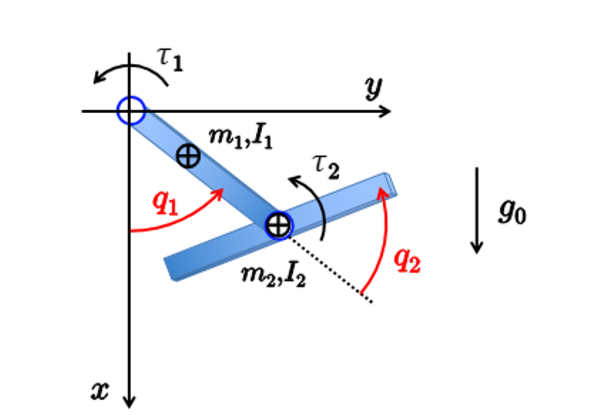

syms q1 q2 dq1 dq2 I1 I2 m1 m2 g0 real
syms d1 d2 F_x F_y real 

% Joint 1
x1 = d1*cos(q1);
y1 = d1*sin(q1);

vx1 = diff(x1,q1)*dq1+diff(x1,q2)*dq2;
vy1 = diff(y1,q1)*dq1+diff(y1,q2)*dq2;

T1_tr = 0.5*m1*[vx1 vy1]*[vx1; vy1;];
T1_rot = 0.5*I1*dq1^2;
T1 = T1_tr+T1_rot;

% Joint 2
x2 = l1*cos(q1);
y2 = l1*sin(q1);

vx2 = diff(x2,q1)*dq1+diff(x2,q2)*dq2;
vy2 = diff(y2,q1)*dq1+diff(y2,q2)*dq2;

omega = [0; 0; dq1+dq2];

T2_tr = 0.5*m2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I2*(omega.')*omega;
T2 = T2_tr+T2_rot;

% Total Kinetic Energy
T=T1+T2

$$T = \frac{I_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}\,{\sin\left(q_{1}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M, steps=100);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} m_{1}\,{d_{1}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & I_{2}\\ I_{2} & I_{2} \end{array}\right)$$


% Potential Energy and Gravity Terms
U1 = m1*g0*d1*cos(q1);
U2 = m2*g0*l1*cos(q1);
U = [U1+U2;];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} -g_{0}\,\sin\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right)\\ 0 \end{array}\right)$$


% Viscous Term
Fdq = [F_x*dq1; F_y*dq2];

% Robot equations
eq1 = M(1,:)*dq1+g_q(1)+Fdq(1)

$$eq1 = \left(\begin{array}{cc} F_{x}\,{\mathrm{dq}}_{1}+{\mathrm{dq}}_{1}\,\left(m_{1}\,{d_{1}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2}\right)-g_{0}\,\sin\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right) & F_{x}\,{\mathrm{dq}}_{1}+I_{2}\,{\mathrm{dq}}_{1}-g_{0}\,\sin\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right) \end{array}\right)$$

eq2 = M(2,:)*dq1+g_q(2)+Fdq(2)

$$eq2 = \left(\begin{array}{cc} F_{y}\,{\mathrm{dq}}_{2}+I_{2}\,{\mathrm{dq}}_{1} & F_{y}\,{\mathrm{dq}}_{2}+I_{2}\,{\mathrm{dq}}_{1} \end{array}\right)$$